# Soving the Heat Equation using FFT for PDEs (Numerically)

% Date: June 5th, 2021
% Location: Ranch, West Texas
% Source: https://www.youtube.com/watch?v=BkA7ncY0b7I

% FFT = Fast Fourier Transform

clear all, close all, clc
a = 1;      % Thermal diffisuvity constant


% Domain
L = 100;    % Length of domain
N = 1000;   % Number of discretization points
dx = L/N;   % Step size
x = -L/2:dx:L/2-dx; % Space vector


% Define discrete wave numbers
% kappa is also called omega, the frequency.
% The 'discrete wave numbers'  is the family of functions that satisfy the
% PDE and the BCs.
kappa = (2*pi/L)*[-N/2:N/2-1]; % ?? Where did this come from?
% Basic frequency is 2pi/domain length, then this is multiplied times every
% node, this will output all of the discrete frequencies. So, why not
% zero times 1000? I mean I guess it makes sense, from -500 to 499, so the
% total nodes is 1000. 
kappa = fftshift(kappa); % rearranges a Fourier transform kappa by shifting the zero-frequency component to the center of the array.

% Initial condition
% The initial condition is a step function, that starts at 0 and goes to 1,
% then back to 0
u0 = 0*x;
u0((L/2 - L/10)/dx:(L/2 + L/10)/dx) = 1; % This represents a step function that goes to 1, starting at 400 and ending at 600 in steps of 1.
% Couldn't we just have used the Heaviside function here instead? -- Well
% this would maybe be a tad bit more convulted, as the step function
% returns +1 for any value > 0, so bringing the value back to zero
% convultes things.

% Simulate in Fourier frequency domain
t = 0:0.1:20;   % Time vector
% This is where all the simulation is happening, is using ode45
[t,uhat]=ode45(@(t,uhat)rhsHeat(t,uhat,kappa,a),t,fft(u0)); % Here is fft!
% ode45 is solving equation (3) (see 6/5/21 notes), which is the ode of the
% heat equation. uhat is the state of the system at each time, and for each
% element of uhat, i.e. for each kappa, (3) is the ode for that row vector.
% rhsHeat, is the right side of (3), it has four arguments, time, the state
% of that element - being integrated, kappa, and alpha.
% ode45 is expecting a vector field that is a function of time and state.
% so the @(t,uhat) is creating on the fly a fun with just those two input
% variables, by taking in the rhsHeat fun with four variables by locking in t and uhat that were defined in the function.
% Summary: We're taking the user-defined function of four variables, locking in kappa and alpha, this forces it to be a function of only two variables that ode45 is expecting.
% Then we give it a vector of t to integrate over, and an initial
% condition, then we give it an initial condition of fft(u0) - which is u0 in space, then we take the Fourier of that to get an initial set of Fourier modes.

% The below takes the solution of moment in time, then performing an
% inverse Fourier on it, in order to plot it
for k = 1:length(t) % iFFT to return to spatial domain
    u(k,:) = ifft(uhat(k,:));
end

## Plot solution in time

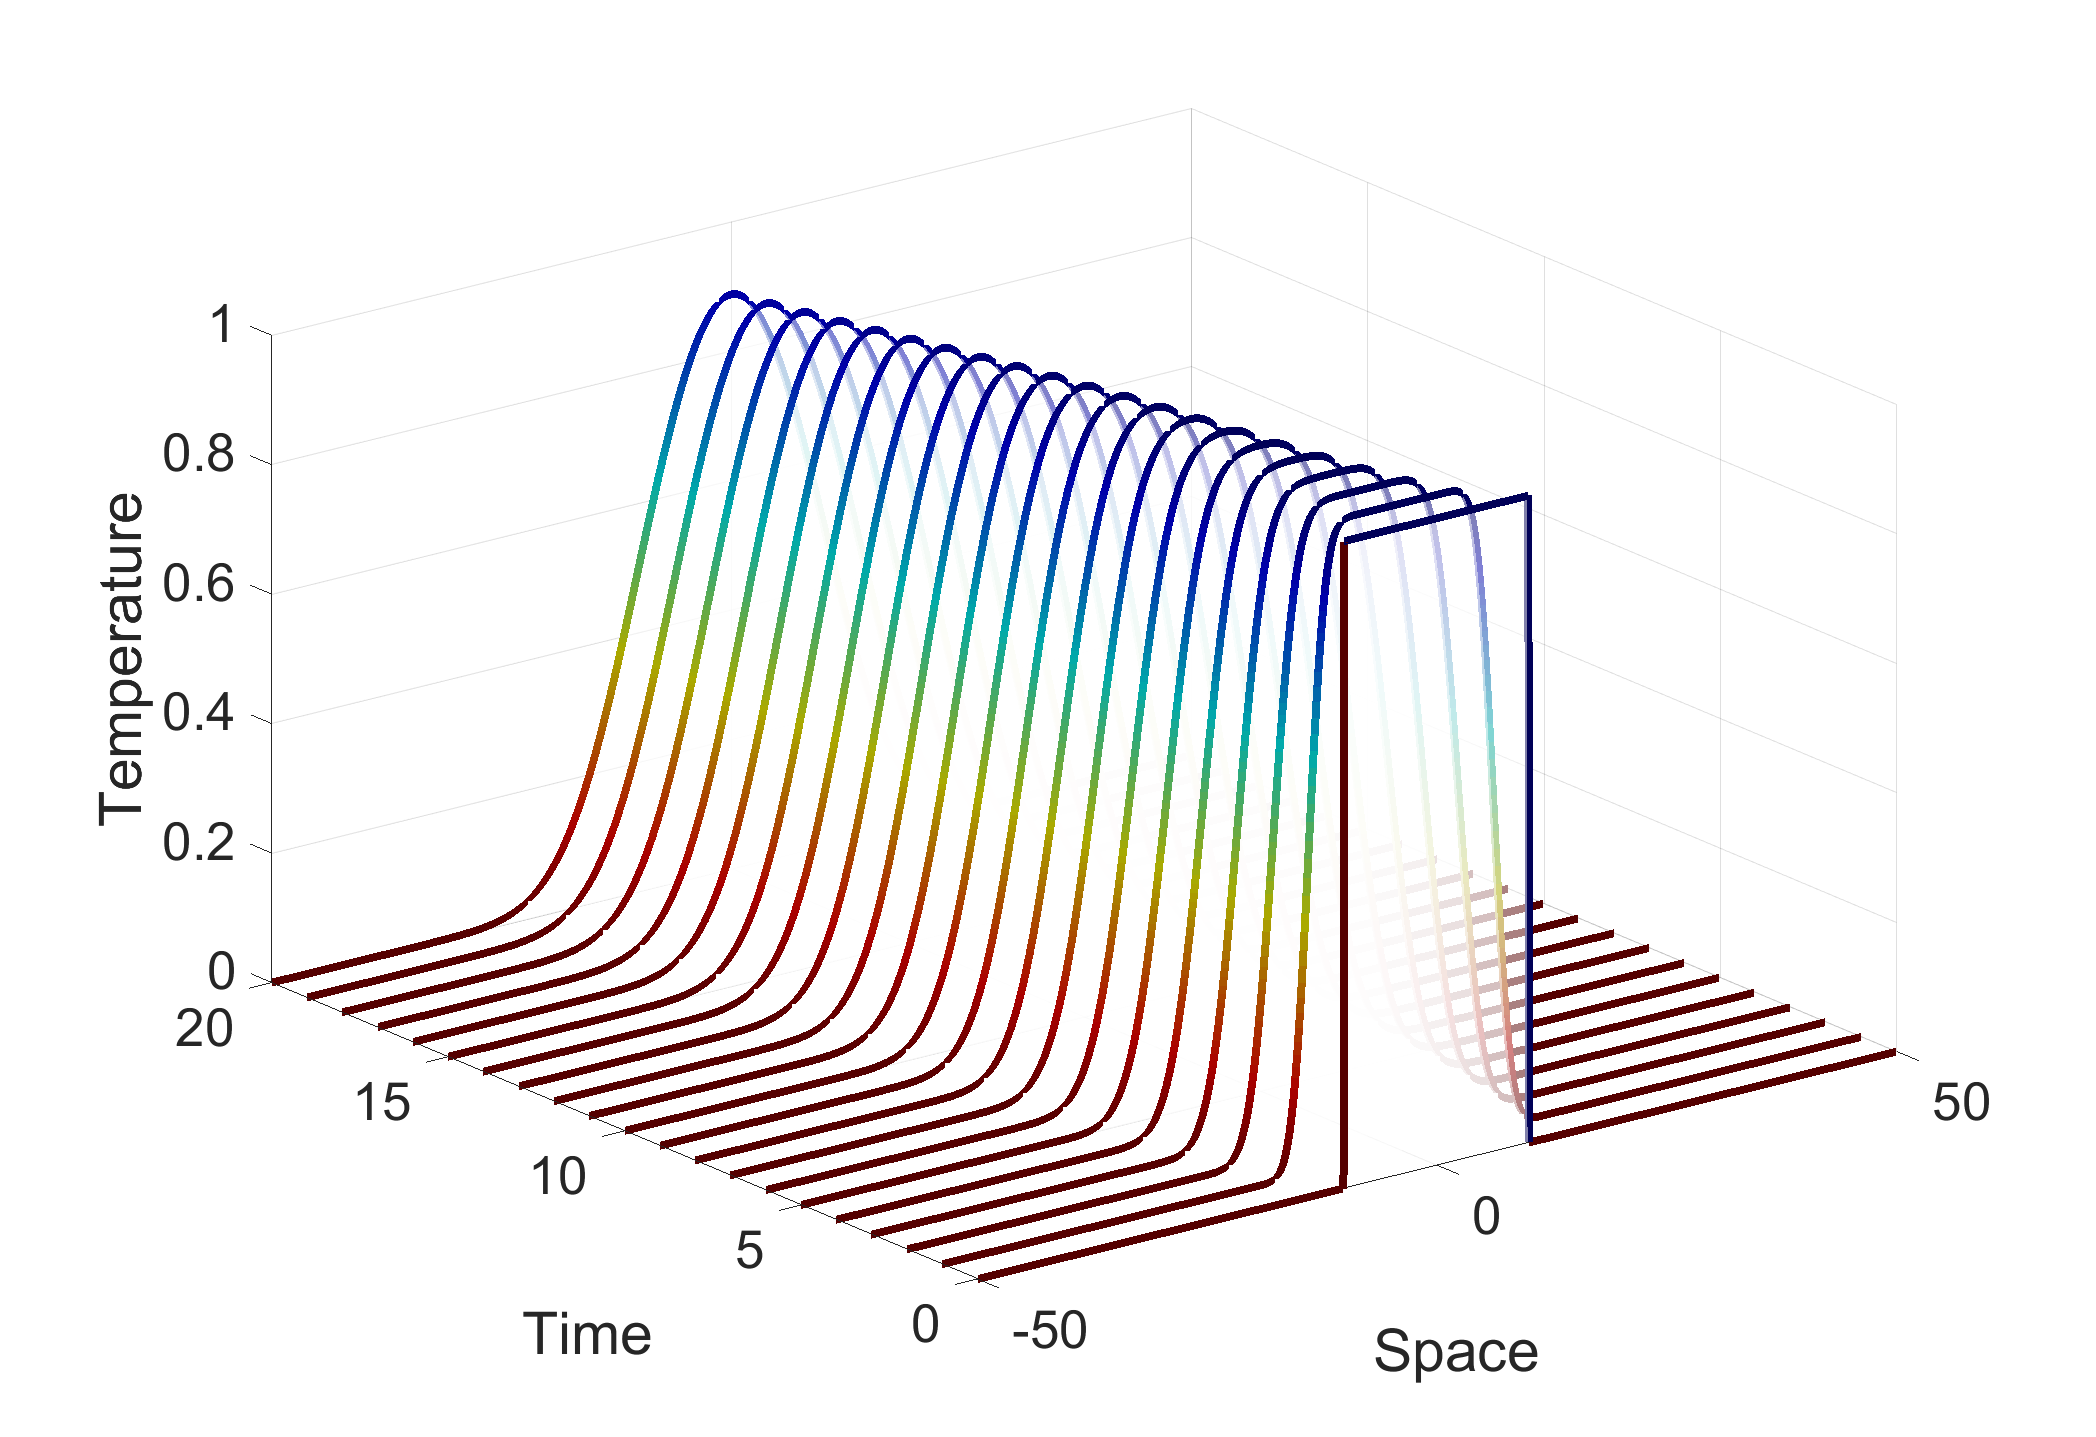

figure, h = waterfall(x,t(1:10:end),(u(1:10:end,:)));
set(h,'LineWidth',5,'FaceAlpha',.5);
colormap(flipud(jet)/1.5)
set(gca,'FontSize',32)
xlabel('Space'); ylabel('Time'); zlabel('Temperature')
set(gcf,'Position',[1500 500 1750 1200])


% He provides a good summary of what this entire code is doing at 12:40...
% 1. Taking our PDE and initial condition u0 -- which is equation 1, the heat
% equation
% 2. We're FFTing it
% 3. We're simulating the (3) system in the Fourier domain; we're walking
% (3) forward using ode45 in the Fourier Transform domain -- uhat is being
% integrated forward in time.  
% 4. Then once the solution in time is found, we take the inverse to find
% the solution in space.

## Movie

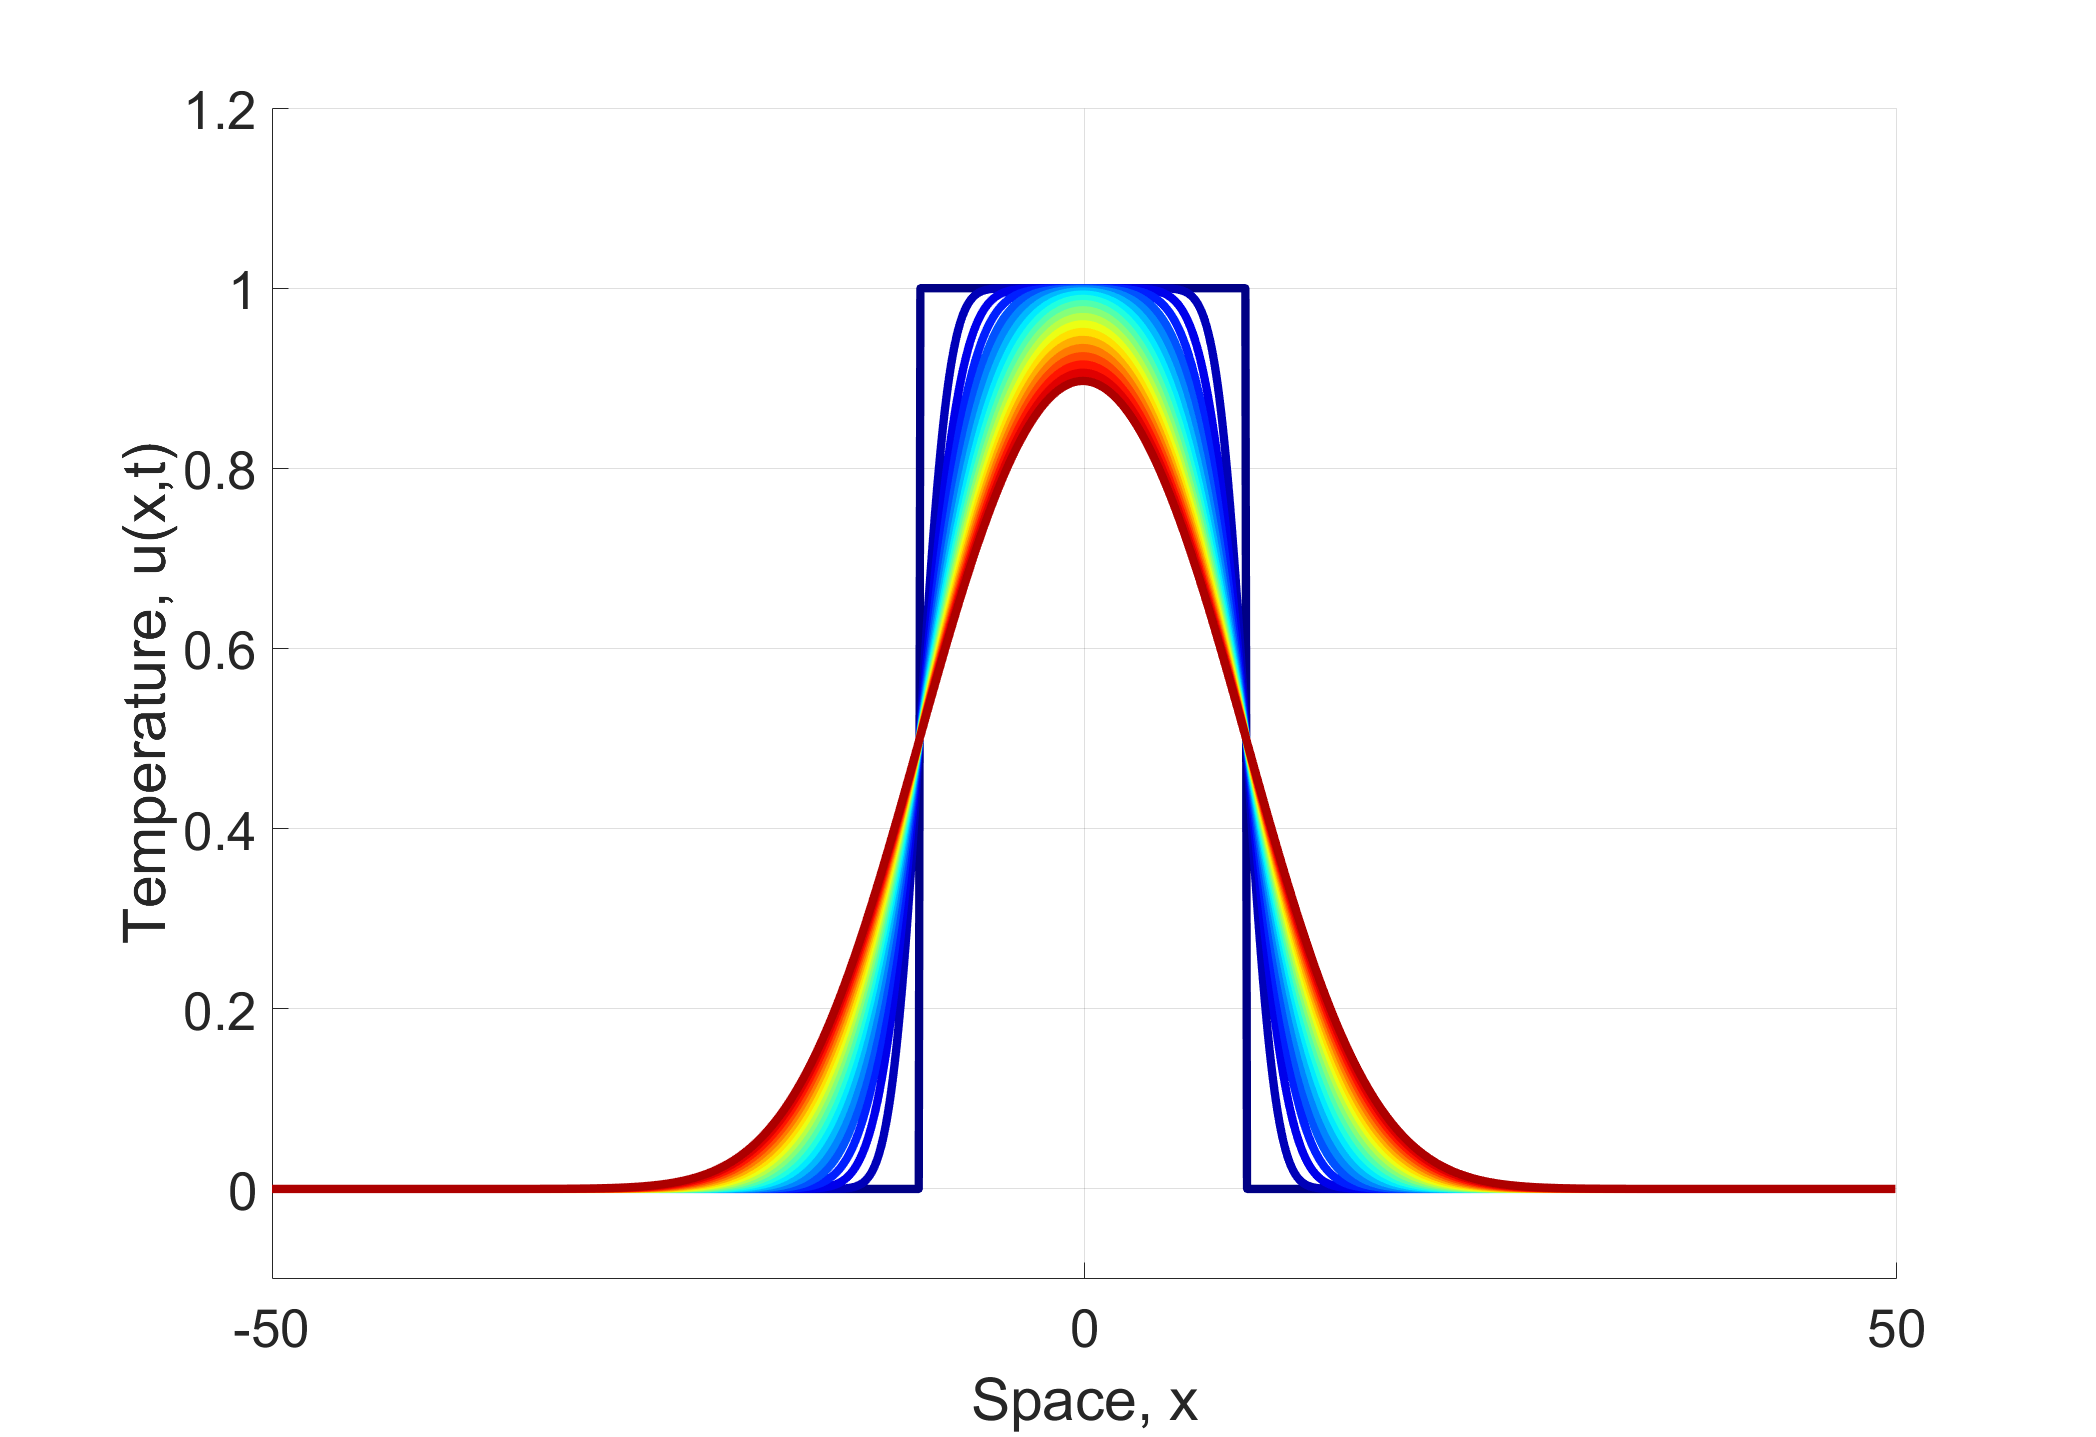

figure
set(gcf,'Position',[1500 500 1750 1200])
xlabel('Space, x')
ylabel('Temperature, u(x,t)')
hold on
set(gca,'FontSize',32)
CC = (colormap(jet(200)));
dt = 0.1;
for k = 1:200
    u(k,:) = ifft(uhat(k,:));
    if(mod(k-1,10)==0)
        plot(x,u(k,:),'Color',CC(k,:),'LineWidth',5)
        ylim([-.1 1.2])
        hold on, grid on, drawnow
    end
end